# ASSIGNMENT-2

AMRUTH.G [240112]

--------------------------------------------------------------------------------------------------------------------------------------------------------

PROBLEM 1

    G(s) =   100 / ( ss + 15s + 50 )

P1(a)

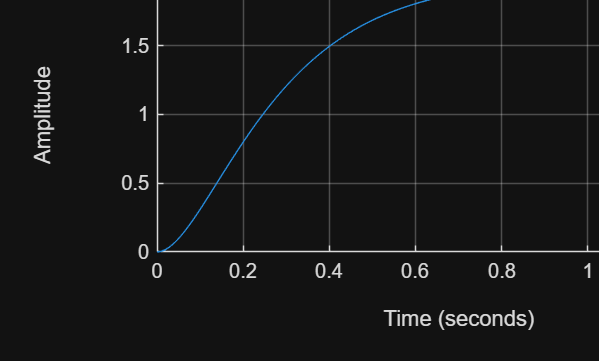

num = [100];
den = [1 15 50];
G = tf(num, den);

figure;
step(G);
title('Open loop Step Response of G(s)');
grid on;


info = stepinfo(G);
fprintf('Rise Time: %.4f sec\n', info.RiseTime);

Rise Time: 0.5180 sec


fprintf('Settling Time: %.4f sec\n', info.SettlingTime);

Settling Time: 0.9200 sec


fprintf('Overshoot: %.2f %%\n', info.Overshoot);

Overshoot: 0.00 %


fprintf('Steady-State Value: %.4f\n', dcgain(G));

Steady-State Value: 2.0000



ess = 1 - dcgain(G);
fprintf('Steady-State Error: %.4f\n', ess);

Steady-State Error: -1.0000


P1(b)

kp = 0.2;
C = tf(kp, 1);
T = feedback(C * G, 1)


T =
 
        20
  ---------------
  s^2 + 15 s + 70
 
Continuous-time transfer function.


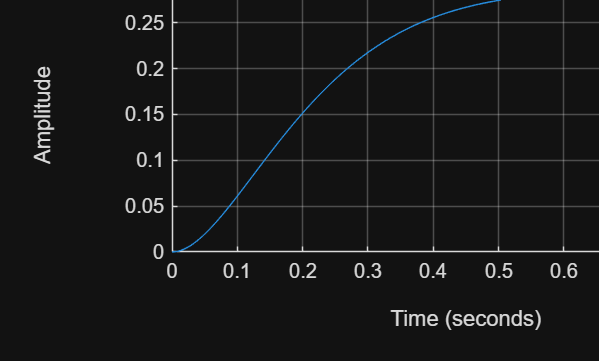


figure;
step(T);
title('Closed-loop Step Response with P Controller');
grid on;


info = stepinfo(T);
fprintf('Rise Time: %.4f sec\n', info.RiseTime);

Rise Time: 0.3427 sec


fprintf('Settling Time: %.4f sec\n', info.SettlingTime);

Settling Time: 0.5571 sec


fprintf('Overshoot: %.2f %%\n', info.Overshoot);

Overshoot: 0.17 %


fprintf('Steady-State Value: %.4f\n', dcgain(T));

Steady-State Value: 0.2857



ess = 1 - dcgain(T);
fprintf('Steady-State Error: %.4f\n', ess);

Steady-State Error: 0.7143



% Why steady state error exists with only P controller
%  Ans. we see T(s) = 20 / (2ss + 15s + 70) ===> T(0) = 2/7
%       and e(inf) = lim(s-->0) sX(s)(1 - T(s)), since X(s) = 1/s
%       we get e(inf) = 1 - 2/7 = 0.7243

P1(c)

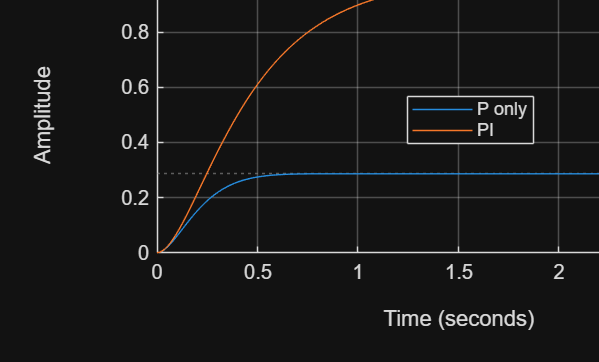

ki = 1;
C = pid(kp, ki, 0);
T_PI = feedback(C * G, 1);

figure;
step(T, T_PI);
legend('P only', 'PI', 'location', 'best');
title('P vs PI (step response)');
grid on;


% info for PI
info = stepinfo(T_PI);
ess = 1 - dcgain(T_PI);

fprintf('--- PI controller ---\n');

--- PI controller ---


fprintf('Rise Time: %.4f sec\n', info.RiseTime);

Rise Time: 0.8843 sec


fprintf('Settling Time: %.4f sec\n', info.SettlingTime);

Settling Time: 1.5894 sec


fprintf('Overshoot: %.2f %%\n', info.Overshoot);

Overshoot: 0.00 %


fprintf('Steady-State Value: %.4f\n', dcgain(T_PI));

Steady-State Value: 1.0000


fprintf('Steady-State Error: %.4f\n', ess);

Steady-State Error: 0.0000



% how integral action eleminated steady state error ?
%  Ans. we see E(s) = X(s)(1 - T(s)) and T(s) = CG / (1 + CG)
%       for X(s) = 1/s, we have sE(s) = 1 - T = 1 / (1 + CG)
%       e(inf) = lim (s-->0) sE(s); since C = kp + ki/s....
%       as s-->0 C-->inf ===> T --> sE(s) = 1 / (1 + CG) --> 0

P1(d)

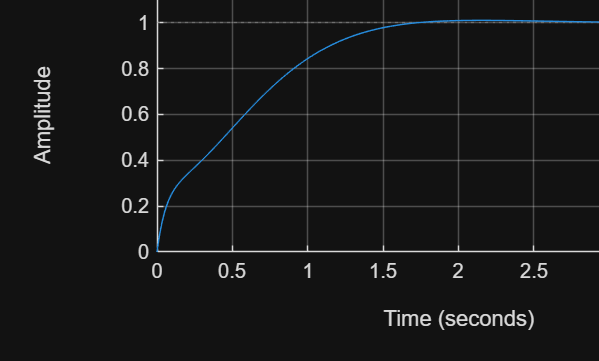

kd = 0.05;
C = pid(kp, ki, kd);
T = feedback(C * G, 1);

figure;
step(T);
title('Closed-loop Step Response with PID Controller');
grid on;


info = stepinfo(T);
ess = 1 - dcgain(T);

fprintf('--- PI controller ---\n');

--- PI controller ---


fprintf('Rise Time: %.4f sec\n', info.RiseTime);

Rise Time: 1.1228 sec


fprintf('Settling Time: %.4f sec\n', info.SettlingTime);

Settling Time: 1.5087 sec


fprintf('Overshoot: %.2f %%\n', info.Overshoot);

Overshoot: 1.08 %


fprintf('Steady-State Value: %.4f\n', dcgain(T));

Steady-State Value: 1.0000


fprintf('Steady-State Error: %.4f\n', ess);

Steady-State Error: 0.0000



% My Final Kp Ki Kd
%       kp = 0.20
%       ki = 1.00
%       kd = 0.05

PROBLEM 2

    G(s) =   100 / ( ss + 15s + 50 )

    C(s) =    (0.2 + 1/s + 0.05s)        :: kp = 0.2; ki = 1; kd = 0.05

P2(a)

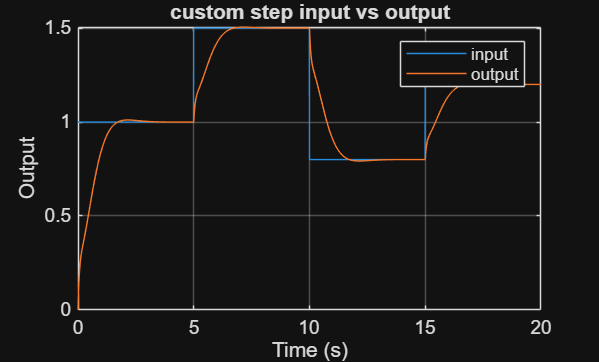

t = 0:0.01:20;
r = zeros(size(t));

r(t >= 0) = 1;     r(t >= 5) = 1.5;
r(t >= 10) = 0.8;  r(t >= 15) = 1.2;

y = lsim(T, r, t);

figure;
plot(t, r); hold on;
plot(t, y);
legend('input', 'output');
title('custom step input vs output');
xlabel('Time (s)');
ylabel('Output');
grid on;

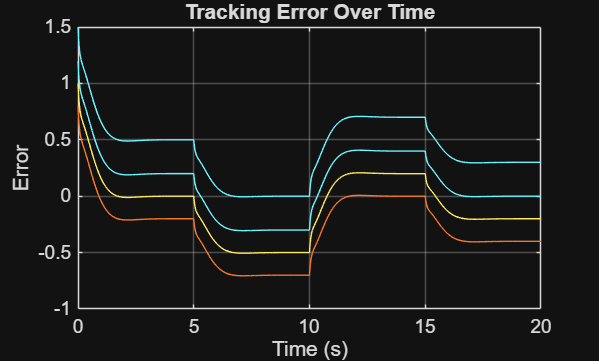


e = r - y;

figure;
plot(t, e);
title('Tracking Error Over Time');
xlabel('Time (s)');
ylabel('Error');
grid on;

P2(b)

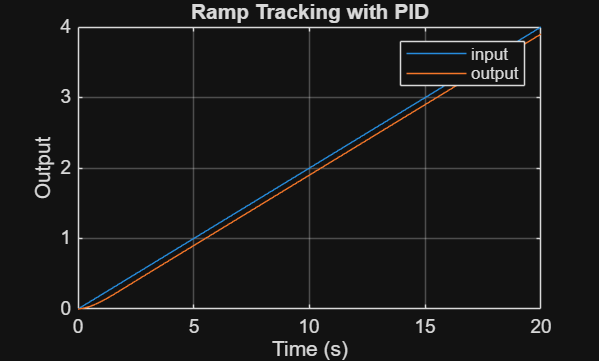

t = 0:0.01:20;
r = 0.2 * t;

y = lsim(T, r, t);
e = r - y;

figure;
plot(t, r); hold on;
plot(t, y);
legend('input', 'output');
title('Ramp Tracking with PID');
xlabel('Time (s)');
ylabel('Output');
grid on;

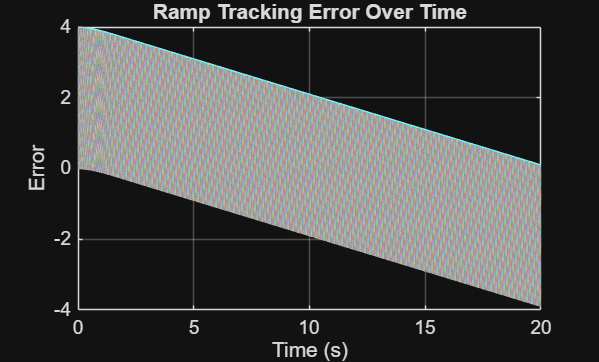


figure;
plot(t, e);
title('Ramp Tracking Error Over Time');
xlabel('Time (s)');
ylabel('Error');
grid on;


% Calculate steady state tracking error :
%   Ans. e(t) = r(t) - y(t) ==> E(s) = R(s)(1 - T(s))
%        ==> sE(s) = 0.2 * ((s * (1 + C(s)G(s)) ) whole inverse)
%        ==> lim (s-->0) sE(s) = e(inf) = 0.2 / (1 + 2Ki),
%        since ki = 1, we get e(inf) = 1/15 = 0.0666

% why PID may struggle with ramp tracking ?
%   Ans. Because the PID controller adds a pole at origin (from Ki/s)
%        This pole makes it Type-1, mathematically e(inf) is non zero
%        and less than inf. hence PID struggles with ramp tracking.
%        whereas PID fails to track parabola completely (ess --> inf)
%        and PID is sucessful in tracking step input (ess --> 0)

P2(c)

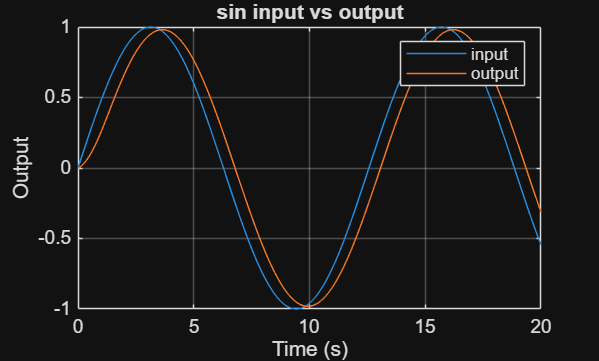

t = 0:0.01:20;
r = sin(0.5*t);

y = lsim(T, r, t);
e = r - y;

figure;
plot(t, r); hold on;
plot(t, y);
legend('input', 'output');
title('sin input vs output');
xlabel('Time (s)');
ylabel('Output');
grid on;

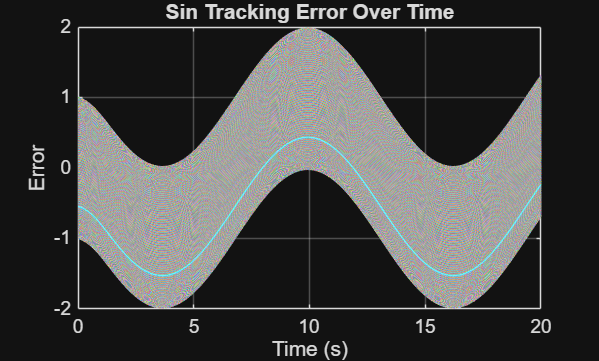


figure;
plot(t, e);
title('Sin Tracking Error Over Time');
xlabel('Time (s)');
ylabel('Error');
grid on;


[mag, phase_dif] = bode(T, 0.5);   % since omega = 0.5 (given)
fprintf('Phase difference: %.4f\n', phase_dif)

Phase difference: -14.3761



% Which PID parameter affects Sine input the most ?
%   Ans. 
%       
%  

PROBLEM 3

    G(s) =    50 / ( sss + 8ss + 25s + 20 )    

P3(a)

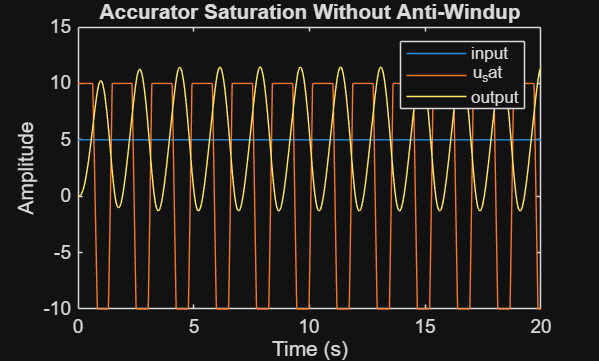

%              
%                       _______    u(t)    _____________    u-sat(t)  ________
%     r(t)---|+  |------| PID |----------->| Accurator |--------------| G(s) |---> y(t)
%            | - |      |_____|            |___________|              |______|
%              ^                                                         |
%              |_________________________________________________________|
%

num = [50];
den = [1 8 25 20];
G = tf(num, den);

dt = 0.01;
T = 20;
t = 0:dt:T;
N = length(t);
r = 5 * ones(1, N);
kp = 5;
ki = 8;
u_lim = 10;

y = zeros(1, N);
u_unsat = zeros(1, N);
u_sat = zeros(1, N);
e_int = zeros(1, N);

y_now = 0;
e_integral = 0;

Gs = ss(G);         
x = zeros(3,1);       

for i = 1:N-1
    e = r(i) - y(i);
    u_unsat(i) = kp*e + ki*e_integral;
    u_sat(i) = max(min(u_unsat(i), 10), -10);
    e_int(i) = e_integral;
    e_integral = e_integral + e*dt;
    [u_step, t_step, x] = lsim(Gs, [u_sat(i); u_sat(i)], [t(i); t(i+1)], x);
    x = x(end, :).';
    y(i+1) = Gs.C * x + Gs.D * u_sat(i); 
end

u_unsat(N) = u_unsat(N-1);
u_sat(N) = u_sat(N-1);
e_int(N) = e_integral;

figure;
plot(t, r); hold on;
plot(t, u_sat);
plot(t, y);
legend('input', 'u_sat', 'output');
xlabel('Time (s)');
ylabel('Amplitude');
title('Accurator Saturation Without Anti-Windup');

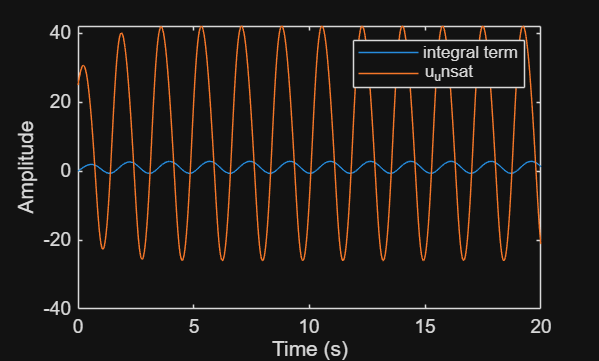


figure;
plot(t, e_int); hold on;
plot(t, u_unsat);
legend('integral term', 'u_unsat');
xlabel('Time (s)');
ylabel('Amplitude');


% When does saturation occur ?
%   Ans. at t = 0, r(0) = 5 and u_unsat(0) = kp*5 = 25 ==> u_sat(0) = 10;

% What happens to the integral error term ?
%   Ans. When u_sat is 10 it keeps increasing, while u_sat = -10, it keeps decreasing

% How does this affect overshoot and settling time ?
%   Ans. Even when u_sat becomes -10, for a while the accumilated integral term keeps driving the system
%        forward beyond 5 causing very high overshoot. This dealays the settling time further (hence settling
%        time increases). Actually it never settles, it keeps oscilating

P3(b)

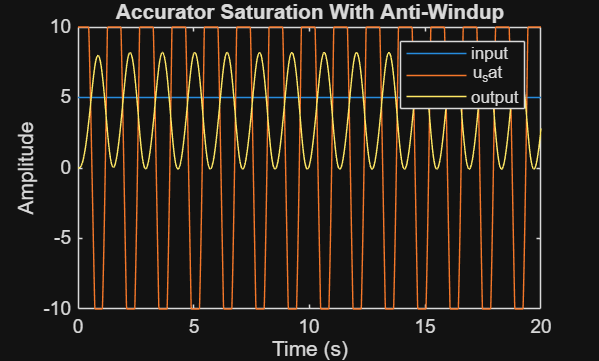

kt = sqrt(ki);

y_aw = zeros(1, N);
u_unsat_aw = zeros(1, N);
u_sat_aw = zeros(1, N);
e_int_aw = zeros(1, N);

y_now = 0; 
Gs = ss(G);         
x = zeros(3,1);
e_integral = 0;

Gs = ss(G);         
x = zeros(3,1);       

for i = 1:N-1
    e = r(i) - y_aw(i);
    u_unsat_aw(i) = kp*e + ki*e_integral;
    u_sat_aw(i) = max(min(u_unsat_aw(i), 10), -10);
    e_int_aw(i) = e_integral;
    e_integral = e_integral + (e + (u_sat_aw(i) - u_unsat_aw(i))/kt ) * dt;
    [u_step, t_step, x] = lsim(Gs, [u_sat_aw(i); u_sat_aw(i)], [t(i); t(i+1)], x);
    x = x(end, :).';
    y_aw(i+1) = Gs.C * x + Gs.D * u_sat(i); 
end

u_unsat_aw(N) = u_unsat_aw(N-1);
u_sat_aw(N) = u_sat_aw(N-1);
e_int_aw(N) = e_integral;

figure;
plot(t, r); hold on;
plot(t, u_sat_aw);
plot(t, y_aw);
legend('input', 'u_sat', 'output');
xlabel('Time (s)');
ylabel('Amplitude');
title('Accurator Saturation With Anti-Windup');

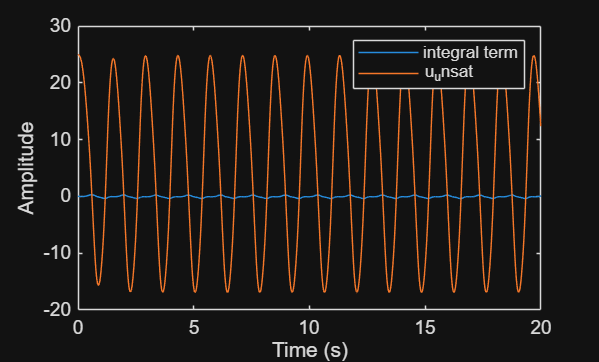


figure;
plot(t, e_int_aw); hold on;
plot(t, u_unsat_aw);
legend('integral term', 'u_unsat');
xlabel('Time (s)');
ylabel('Amplitude');

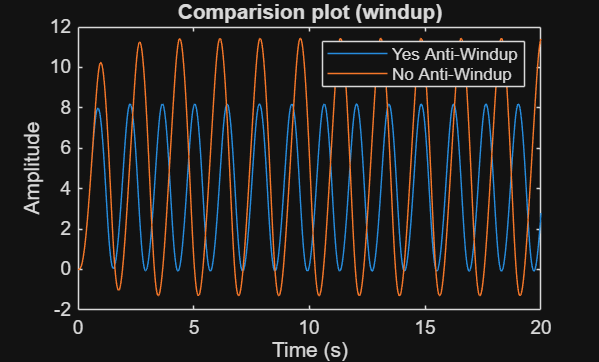


% Comparision plot :
figure;
plot(t, y_aw); hold on;
plot(t, y);
legend('Yes Anti-Windup', 'No Anti-Windup');
xlabel('Time (s)');
ylabel('Amplitude');
title('Comparision plot (windup)');


% Table showing Quantitative improvement :

setpoint = 5;
tol = 0.1;  % 2% settling band (±0.1 around 5)
% --- Without Anti-Windup ---
max_overshoot_no = (max(y) - setpoint) / setpoint * 100;
sat_time_no = sum(abs(u_sat) >= 9.999) * dt;  % counts steps at full saturation
% Settling time (string since it doesn't settle)
settling_no = '>20 s (does not settle)';
% --- With Anti-Windup ---
max_overshoot_aw = (max(y_aw) - setpoint) / setpoint * 100;
sat_time_aw = sum(abs(u_sat_aw) >= 9.999) * dt;
settling_aw = '>20 s (does not settle)';
% Display
disp(['Without AW - Overshoot: ' num2str(max_overshoot_no, '%.2f') '%']);

Without AW - Overshoot: 128.87%


disp(['Without AW - Settling time: ' settling_no]);

Without AW - Settling time: >20 s (does not settle)


disp(['Without AW - Saturation time: ' num2str(sat_time_no, '%.2f') ' s']);

Without AW - Saturation time: 16.25 s


disp(['With AW - Overshoot: ' num2str(max_overshoot_aw, '%.2f') '%']);

With AW - Overshoot: 63.85%


disp(['With AW - Settling time: ' settling_aw]);

With AW - Settling time: >20 s (does not settle)


disp(['With AW - Saturation time: ' num2str(sat_time_aw, '%.2f') ' s']);

With AW - Saturation time: 13.73 s



fprintf('Table is on the left section');

Table is on the left section


%    ----------------------------------------------------------------------------
%    |________________________|___Without Anti Windup___|___With Anti Windup____|
%    |  overshoot (%)         |         128.87%         |        63.85 %        |
%    |  Settling time (s)     |           inf           |          inf          |
%    |  Saturation time (s)   |         16.25 s         |        13.73 s        |
%    |________________________|_________________________|_______________________|


% How Back calculations prevent excessive overshoot ?
%   Ans. In the back-calculation method, the integral update becomes I = e(t) + (1/kt) (u_{sat} - u).
%        When unsaturated (u = usat), the extra term is 0, so it integrates e normally. During
%        saturation (e.g., u > 10 so usat=10), u_{sat} - u < 0, adding a negative "back-calculation"
%        term to I. This opposes the positive e (during initial rise), slowing or halting integral 
%        growth—effectively "freezing" I until the actuator can respond. Without this, I keeps ramping
%        unchecked, storing "unusable" energy. When saturation lifts, the bloated I causes over
%        correction (huge overshoot). Here, it caps I at ~15 (vs. ~35 without), halving overshoot and
%        saturation time, while reducing oscillation severity (though gains need tuning for stability).

P3(c)

[A,B,C] = ssdata(G);

Kp = 5; Ki = 8;
Kd = 2; Kt = sqrt(Ki);             
u_max = 10; u_min = -10;

noise_std = 0.05;           
wc = 7;                    
alpha = exp(-wc*dt);

x1 = zeros(size(A,1),1);   
x2 = zeros(size(A,1),1);   

I1 = 0; I2 = 0;

y1 = zeros(1,N); y2 = zeros(1,N);
u1 = zeros(1,N); u2 = zeros(1,N);
u1s = zeros(1,N); u2s = zeros(1,N);
e1 = zeros(1,N); e2 = zeros(1,N);

e_prev = 0;
ef = 0; ef_prev = 0;

for k = 1:N-1

    y1(k) = C*x1;
    yN1 = y1(k) + noise_std*randn;

    e1(k) = r(k) - yN1;
    de1 = (e1(k) - e_prev)/dt;

    u1(k) = Kp*e1(k) + Ki*I1 + Kd*de1;
    u1s(k) = max(min(u1(k),u_max),u_min);

    I1 = I1 + dt*( e1(k) + (1/Kt)*(u1s(k) - u1(k)) );

    x1 = x1 + dt*(A*x1 + B*u1s(k));

    y2(k) = C*x2;
    yN2 = y2(k) + noise_std*randn;

    e2(k) = r(k) - yN2;

    ef = alpha*ef + (1-alpha)*e2(k);
    de2 = (ef - ef_prev)/dt;

    u2(k) = Kp*e2(k) + Ki*I2 + Kd*de2;
    u2s(k) = max(min(u2(k),u_max),u_min);

    I2 = I2 + dt*( e2(k) + (1/Kt)*(u2s(k) - u2(k)) );

    x2 = x2 + dt*(A*x2 + B*u2s(k));

    e_prev = e1(k);
    ef_prev = ef;

end

y1(end) = C*x1;
y2(end) = C*x2;

std_u_unfiltered = std(u1);
std_u_filtered   = std(u2);

fprintf('Std of control (no filter) : %.4f\n', std_u_unfiltered);

Std of control (no filter) : 27.0833


fprintf('Std of control (filtered)  : %.4f\n', std_u_filtered);

Std of control (filtered)  : 13.8526


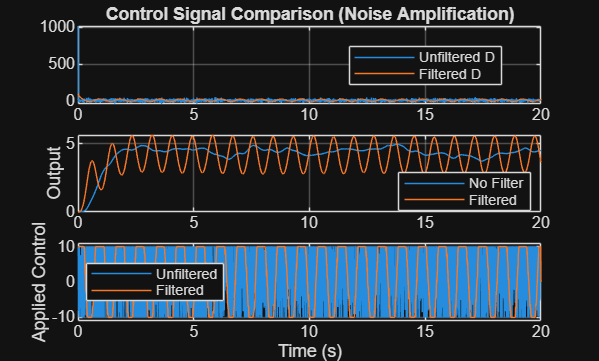


figure;
subplot(3, 1, 1);
plot(t, u1); hold on;
plot(t, u2);
grid on;
legend('Unfiltered D', 'Filtered D');
legend ('Location', 'best');
title('Control Signal Comparison (Noise Amplification)');

subplot(3, 1, 2);
plot(t, y1); hold on;
plot(t, y2);
grid on;
legend('No Filter', 'Filtered');
legend ('Location', 'best');
ylabel('Output');

subplot(3, 1, 3);
plot(t, u1s); hold on;
plot(t, u2s);
grid on;
ylabel('Applied Control');
xlabel('Time (s)');
legend('Unfiltered','Filtered');
legend ('location','best');
ylim([-11 11]);

P3(d)

num = 50;
den = [1 8 25 20];
G = tf(num, den);
[A, B, C, D] = ssdata(G);

u_max = 10;
u_min = -10;

wc = 7;
alpha = exp(-wc*dt);

r = zeros(1,N);

for k = 1:N
    tk = t(k);
    if tk < 2 r(k) = 0.5*tk;                          
    elseif tk < 4 r(k) = 1;                              
    elseif tk < 8 r(k) = 1 + 0.5*sin(2*pi*(tk-4));       
    elseif tk < 10 r(k) = 2;                               
    elseif tk < 15 r(k) = 2 - 0.3*(tk-10);                
    else r(k) = 0.5; 
    end
end

x = zeros(size(A,1),1);
integral_error = 0;

y  = zeros(1,N);
e  = zeros(1,N);
u  = zeros(1,N);
u_sat = zeros(1,N);

e_filt = 0;
e_filt_prev = 0;

for k = 1:N-1
    y(k) = C*x;
    e(k) = r(k) - y(k);
    e_filt = alpha*e_filt + (1-alpha)*e(k);
    de = (e_filt - e_filt_prev)/dt;
    u(k) = Kp*e(k) + Ki*integral_error + Kd*de;
    u_sat(k) = max(min(u(k),u_max),u_min);
    integral_error = integral_error + dt*( e(k) + (1/Kt)*(u_sat(k) - u(k)) );
    x = x + dt*(A*x + B*u_sat(k));
    e_filt_prev = e_filt;
end

y(end) = C*x;

e_rms = sqrt(mean(e.^2));
fprintf('RMS tracking error: %.4f\n', e_rms);

RMS tracking error: 1.0661


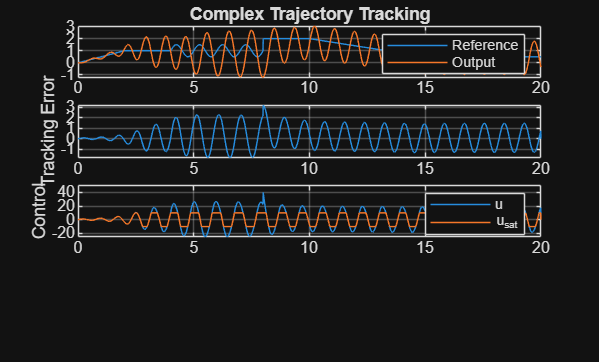


figure;

subplot(4, 1, 1);
plot(t, r); hold on;
plot(t, y);
legend('input', 'output');
grid on;
legend('Reference','Output');
title('Complex Trajectory Tracking');

subplot(4, 1, 2);
plot(t, e);
grid on;
ylabel('Tracking Error');

subplot(4, 1, 3);
plot(t, u); hold on;
plot (t, u_sat);
legend('u_unsat', 'u_sat');
grid on;
ylabel('Control');
legend('u','u_{sat}');